# Empenage Geometery

clear; close; clc;

## Define Parameters

% Horizontal Tail
lambda_h = 16/28; % horizontal tail taper ratio (~)
S_h = 14.3 * convlength(1,"ft","m")^2; % planform area of horizontal Tail (m)
Lambda_LE_h = deg2rad(15.75); % leading edge sweep angle (radians)
c_r_h = convlength(20,"in","m"); % root cord of horizontal tail (m)

% Verticle Tail
lambda_v = 20/30; % verticle tail taper ratio (~)
S_v = 14 * convlength(1,"ft","m")^2; % planform area of verticle Tail (m)
Lambda_LE_v = deg2rad(35); % leading edge sweep angle (radians)
%c_r_v = convlength(30,"in","m"); % root cord of horizontal tail (m)
c_r_v = convlength(30,"in","m"); % root cord of horizontal tail (m)

## Horizontal-Tail

b_h = 2 * S_h / (c_r_h * (1+lambda_h)) % compute span

b_h = 3.3284


% locate Mean Geomateric Cord (M.G.C)
[c_bar_h, x_mgc_h, y_mgc_h] = MeanGeometricCord(c_r_h, b_h, lambda_h, Lambda_LE_h) % compute the MGC

c_bar_h = 0.4090

x_mgc_h = 0.2133

y_mgc_h = 0.7565


c_t_h = c_r_h * lambda_h; % tip Cord

% Determine pont that define the airfoil
x_coords_hTail = [0, b_h/2, b_h/2, 0];
y_coords_hTail = -[0, b_h/2 * sin(Lambda_LE_h), b_h/2 * sin(Lambda_LE_h) + c_t_h, c_r_h];

% plot semi-span
figure;
plot(x_coords_hTail, y_coords_hTail,"-x");
title("Semi-Span Horizontal Tail"); xlabel("Wing Station, y, (m)"); ylabel("Location Relative to Root Leading Edge, -x, (m)");
axis equal;

% add Mean Geometric cord to plot
hold on;
c_bar_h

c_bar_h = 0.4090

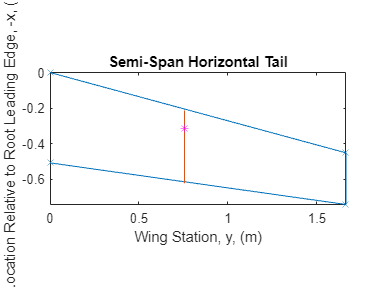

plot([y_mgc_h, y_mgc_h], -[x_mgc_h, x_mgc_h + c_bar_h])
plot(y_mgc_h, -(x_mgc_h + c_bar_h/4), "Marker","*", "MarkerEdgeColor", "magenta")
axis equal;
xlim([0, Inf]); ylim([-Inf, 0]);

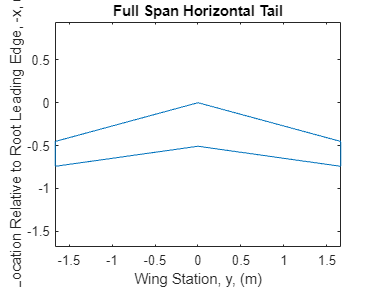


% plot full-span
figure;
plot([x_coords_hTail, -fliplr(x_coords_hTail)], [y_coords_hTail,fliplr(y_coords_hTail)])
title("Full Span Horizontal Tail"); xlabel("Wing Station, y, (m)"); ylabel("Location Relative to Root Leading Edge, -x, (m)");
axis equal;


% create variable to save
hTailCoordinates = [x_coords_hTail; y_coords_hTail];
hTailMeanGeometricCord = [c_bar_h, x_mgc_h, y_mgc_h];

save("Arychtas_hTail_Coordinates_Class_I_V_0.mat","hTailCoordinates","hTailMeanGeometricCord");


## Verticle Tail

b_v = 2 * S_v / (c_r_v * (1+lambda_v)) % compute span

b_v = 2.0483


% locate Mean Geomateric Cord (M.G.C)
[c_bar_v, x_mgc_v, y_mgc_v] = MeanGeometricCord(c_r_v, 2*b_v, lambda_v, Lambda_LE_v) % compute the MGC

c_bar_v = 0.6435

x_mgc_v = 0.6693

y_mgc_v = 0.9559


c_bar_v = 2/3 * c_r_v * (1 + lambda_v + lambda_v^2) / (1 + lambda_v); % mean geometric cord (length)
y_mgc_v = b_v*2 * (1 + 2*lambda_v) / (6*(1+lambda_v));
x_mgc_v = y_mgc_v * sin(Lambda_LE_v);


c_t_v = c_r_v * lambda_v; % tip Cord

% Determine pont that define the airfoil
z_coords_vTail = [0, b_v, b_v, 0];
y_coords_vTail = -[0, b_v * sin(Lambda_LE_v), b_v * sin(Lambda_LE_v) + c_t_v, c_r_v];

% plot semi-span
figure;
plot(y_coords_vTail, z_coords_vTail, "-x");
title("Semi-Span Verticle Tail"); xlabel("Wing Station, y, (m)"); ylabel("Location Relative to Root Leading Edge, -x, (m)");
axis equal;
ylim([0, Inf]);
xlim([-( b_v * sin(Lambda_LE_v) + c_t_v),0])

% add Mean Geometric cord to plot
hold on;
c_bar_v

c_bar_v = 0.6435

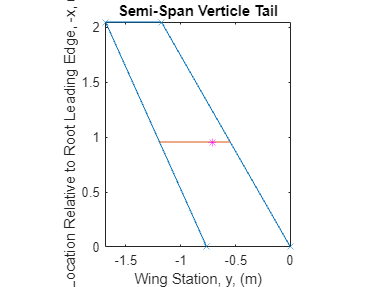

plot( -[x_mgc_v, x_mgc_v + c_bar_v],[y_mgc_v, y_mgc_v])
plot(-(x_mgc_v + c_bar_v/4), y_mgc_v, "Marker","*", "MarkerEdgeColor", "magenta")


% create variable to save
vTailCoordinates = [z_coords_vTail; y_coords_vTail];
vTailMeanGeometricCord = [c_bar_v, x_mgc_v, y_mgc_v];

save("Arychtas_vTail_Coordinates_Class_I_V_0.mat","vTailCoordinates","vTailMeanGeometricCord");
